clear all; clc; close all;

% Definizione dei parametri globali
global lunghezza_passo raggio_curva num_iterazioni punti direzioni

% Definizione dei parametri
lunghezza_passo = 15.0; % Lunghezza del passo in avanti
raggio_curva = 15.0; % Raggio di curvatura per le curve a destra e sinistra
num_iterazioni = 10; % Numero di iterazioni

% Punto iniziale (centro degli assi)
punto_iniziale = [50, 40];

% Inizializzazione del vettore per i punti
punti = zeros(((num_iterazioni + 1)^3), 2);
punti(1, :) = punto_iniziale;

punto_finale_avanti = zeros(length(punti),2);
punto_finale_destra = zeros(length(punti),2);
punto_finale_sinistra = zeros(length(punti),2);

% Inizializzazione del vettore per le direzioni
direzioni = zeros(3 * ((num_iterazioni + 1)^3), 1);
direzioni(1) = pi / 2; % Inizialmente verso l'alto

% Contatore dei punti
contatore = 1;

% Load map from a. mat file
data = load('map_straight_with_roundabout.mat');
% data = load('test/Files_mat/maps_5_1.mat');  % Sostituisci 'nome_file_mappa.mat' con il tuo percorso e nome del file

% Check available fields in 'data' structure
disp(fieldnames(data));

    {'map_straight_with_roundabout'}



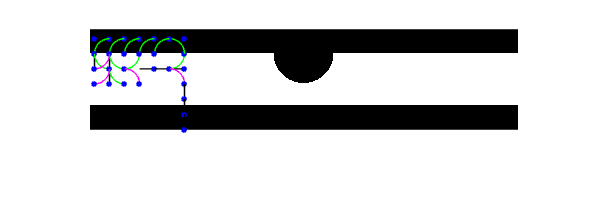

Index in position 1 exceeds array bounds. Index must not exceed 100.

Error in test_RSC_24_2>calculate_points (line 108)
        if check_valid_point(punto_avanti, map) && adjacency_matrix(round(punto_avanti(2)), round(punto_avanti(1))) == 0

Error in test_RSC_24_2>cal


% Extract map from data structure
map = data.map_straight_with_roundabout;
% map = data.invertedImage;
% Plot initialization
figure;
imshow(map);
hold on;

% Avvio della ricorsione dal punto iniziale
calculate_points(punto_iniziale, 0, 1, contatore, map);


% Aggiunta delle annotazioni finali
title('Primitive Reed-Sheep Curves Iterative');
% xlabel('X');
% ylabel('Y');
% legend('Linee in avanti', 'Punti successivi', 'Curve a destra', 'Curve a sinistra');
% axis equal;
grid on;

## FUNCTIONS

function calculate_points(punto_corrente, angolo_corrente, iterazione, contatore, map)
    global lunghezza_passo raggio_curva num_iterazioni punti direzioni

    persistent adjacency_matrix  % Matrice di adiacenza per tenere traccia dei punti visitati
    if isempty(adjacency_matrix)
        adjacency_matrix = zeros(size(map));  % Inizializza la matrice con zeri
    end

    if iterazione > num_iterazioni
        return;
    end
    
    % Assicurati che punto_corrente sia un vettore riga
    punto_corrente = punto_corrente(:)';
    
    % Controllo se il punto corrente è già stato visitato
    if check_valid_point(punto_corrente, map) && adjacency_matrix(round(punto_corrente(2)), round(punto_corrente(1))) == 0
        % Segna il punto corrente come visitato nella matrice di adiacenza
        adjacency_matrix(round(punto_corrente(2)), round(punto_corrente(1))) = 1;
        
        % Calcolo del punto successivo in avanti
        punto_avanti = punto_corrente + lunghezza_passo * [cos(angolo_corrente), sin(angolo_corrente)];
        
        % Aggiornamento del contatore e salvataggio del punto e della direzione
        contatore = contatore + 1;
        punti(contatore, :) = punto_avanti;
        direzioni(contatore) = angolo_corrente;
        
        % Centro della circonferenza per la curva a destra
        centro_destra = punto_corrente + raggio_curva * [cos(angolo_corrente - pi/2), sin(angolo_corrente - pi/2)];
        
        % Centro della circonferenza per la curva a sinistra
        centro_sinistra = punto_corrente + raggio_curva * [cos(angolo_corrente + pi/2), sin(angolo_corrente + pi/2)];
        
        % Angoli per generare i quarti di cerchio
        theta_destra = linspace(angolo_corrente + pi/2, angolo_corrente, 100);
        theta_sinistra = linspace(angolo_corrente - pi/2, angolo_corrente, 100);
        
        % Calcolo dei punti lungo le curve a destra e sinistra
        x_destra = centro_destra(1) + raggio_curva * cos(theta_destra);
        y_destra = centro_destra(2) + raggio_curva * sin(theta_destra);
        punto_finale_destra = [x_destra(end), y_destra(end)];
        
        x_sinistra = centro_sinistra(1) + raggio_curva * cos(theta_sinistra);
        y_sinistra = centro_sinistra(2) + raggio_curva * sin(theta_sinistra);
        punto_finale_sinistra = [x_sinistra(end), y_sinistra(end)];
        
        % Aggiunta dei punti e delle curve al plot
        hold on;



        
        % Chiamata ricorsiva per i nuovi punti finali solo se non sono stati visitati
        if check_valid_point(punto_avanti, map) && adjacency_matrix(round(punto_avanti(2)), round(punto_avanti(1))) == 0
            plot([punto_corrente(1), punto_avanti(1)], [punto_corrente(2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
            plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
            calculate_points(punto_avanti, angolo_corrente, iterazione + 1, contatore, map);
        end
        
        if check_valid_point(punto_finale_destra, map) && adjacency_matrix(round(punto_finale_destra(2)), round(punto_finale_destra(1))) == 0
            plot(x_destra, y_destra, 'g', 'LineWidth', 0.5);
            plot(x_destra(end), y_destra(end), 'b.', 'MarkerSize', 10);
            calculate_points(punto_finale_destra, angolo_corrente - pi/2, iterazione + 1, contatore, map);
        end
        
        if check_valid_point(punto_finale_sinistra, map) && adjacency_matrix(round(punto_finale_sinistra(2)), round(punto_finale_sinistra(1))) == 0
            plot(x_sinistra, y_sinistra, 'm', 'LineWidth', 0.5);
            plot(x_sinistra(end), y_sinistra(end), 'b.', 'MarkerSize', 10);
            calculate_points(punto_finale_sinistra, angolo_corrente + pi/2, iterazione + 1, contatore, map);
        end
    end
end

function valid = check_valid_point(point, map)
    % Controlla se il punto è all'interno dei limiti della mappa
    valid = all(point >= 1) && all(point <= size(map));
end



Funzione per plottare

function plotGraph(punto_finale, punto_avanti, destra, sinistra)

    % Plot della linea dal punto precedente al punto in avanti
    plot([punto_finale(1), punto_avanti(1)], [punto_finale(2), punto_avanti(2)], 'k-', 'LineWidth', 0.5);
    
    % Plot del punto in avanti
    plot(punto_avanti(1), punto_avanti(2), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a destra
    plot(destra(1,:), destra(2,:), 'g', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a destra (punto blu)
    plot(destra(1,end), destra(2,end), 'b.', 'MarkerSize', 10);
    
    % Plot della curva a sinistra
    plot(sinistra(1,:), sinistra(2,:), 'm', 'LineWidth', 0.5);
    
    % Plot dell'ultimo punto della curva a sinistra (punto blu)
    plot(sinistra(1,end), sinistra(2,end), 'b.', 'MarkerSize', 10);
end
